Call the ROC script

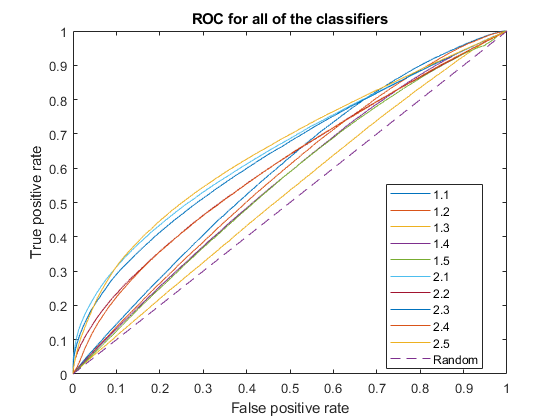

AUC11 = 0.5916

AUC12 = 0.5770

AUC13 = 0.5267

AUC14 = 0.5634

AUC15 = 0.5582

AUC21 = 0.6546

AUC22 = 0.6098

AUC23 = 0.6447

AUC24 = 0.6070

AUC25 = 0.6599

roc_v7_first_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans = 0.9901

ans = 141

ans = 0.9618

ans = 0.0413

ans = 0.9618

ans = 0.6802

ans = 0.8088

Classifier 2

ans = 0.9865

ans = 158

ans = 0.9297

ans = 0.0717

ans = 0.9297

ans = 0.7927

ans = 0.8825

Classifier 3

ans = 0.9969

ans = 175

ans = 0.7185

ans = 0.2893

ans = 0.7185

ans = 0.9238

ans = 0.9475

Classifier 4

ans = 0.9940

ans = 150

ans = 0.8857

ans = 0.1196

ans = 0.8857

ans = 0.7565

ans = 0.8374

Classifier 5

ans = 0.9987

ans = 126

ans = 0.8696

ans = 0.1323

ans = 0.8696

ans = 0.6233

ans = 0.7125

Classifier 6

ans = 0.0308

ans = 39

ans = 0.9991

ans = 9.2466e-04

ans = 0.9991

ans = 0.0972

ans = 0.3085

Classifier 7

ans = 0.0015

ans = 35

ans = 0.9829

ans = 0.0170

ans = 0.9829

ans = 0.1120

ans = 0.2511

Classifier 8

ans = 8.8451e-04

ans = 38

ans = 0.9977

ans = 0.0022

ans = 0.9977

ans = 0.1017

ans = 0.2930

Classifier 9

ans = 0.0012

ans = 49

ans = 0.9805

ans = 0.0187

ans = 0.9805

ans = 0.1775

ans = 0.3303

Classifier 10

ans = 7.2166e-06

ans = 47

ans = 0.9992

ans = 7.7766e-04

ans = 0.9992

ans = 0.1288

ans = 0.3580

Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val = 0.9992

ind = 10

Plot binomial distributions for that classifier

ytrue = binopdf(k,N,selectedPoints(ind,7));
prandom = psame * selectedPoints(ind,7) + (1 - psame) * selectedPoints(ind,6)

prandom = 0.1600

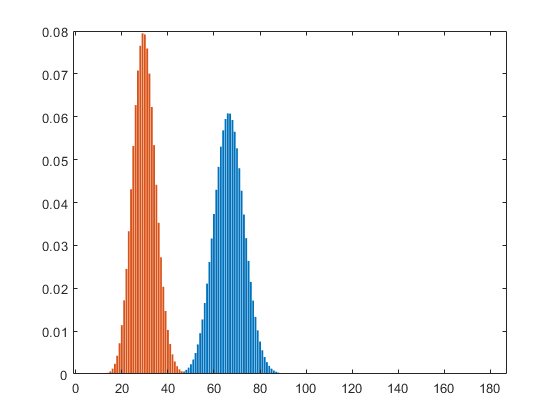

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

Which gives us, according to Hanley's explanation

bitErrors = 521*(1-selectedPoints(ind,3))

bitErrors = 0.4145

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end
cost = cost * 521

cost = 135981

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 17.0530

Save results

save('./results_characterization/v7_first_op.mat','selectedPoints');